assert(endsWith(pwd, "non-ferromagnetic metal plate with hole in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear;
close all;

## Distributed Current Source

#### Electromagnet

EM.num = 2;
EM.inner_radius = [3.75e-3 3.75e-3]; % (m)
EM.outer_radius = [6.00e-3 6.00e-3]; % (m)
EM.length       = [4.00e-3 4.00e-3]; % (m)
EM.Nturns = [60 60];

EM_pos = [-10e-3, 0, 4e-3
            6e-3, 0, 4e-3]; % (m)
EM = SetPositionRotation3D(EM, EM_pos, repmat([1,0,0],EM.num,1), repmat([0],EM.num,1));
clear EM_pos

#### Sensor

Sensor.num = 20;
Sensor.side_length = 1e-3;

Sensor_pos = [
    linspace(-30e-3,30e-3,Sensor.num); 
    0      * ones(1,Sensor.num); 
    1.5e-3 * ones(1,Sensor.num)];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos', repmat([1,0,0],Sensor.num,1), repmat([0],Sensor.num,1));
clear Sensor_pos

#### Model

vertex_file = 'plate_l72_t2_hole_d12_vertex.csv';
element_file = 'plate_l72_t2_hole_d12_element.csv';
Model = BuildModel3D('File', vertex_file, element_file, 1e-3);

build model took 0.10 seconds


clear vertex_file element_file

Model.conductivity = 7.407e5 * ones(1,Model.num_elms); % (S/m)
Model.relative_permittivity = 1 * ones(1,Model.num_elms); % (1)

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, EM);

build governing equation took 123.73 seconds


#### Solve in frequency domain

EM.frequency_domain.current = [1 -1]; % (A)
EM.frequency_domain.current_density = EM.frequency_domain.current .* EM.Nturns ./ ((EM.outer_radius-EM.inner_radius).*EM.length); % (A/m^2)
EM.frequency_domain.frequency = 20000; % (Hz)

[Model, EM, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, EM, Sensor);

solve current density took 3.99 seconds
solve magnetic flux density took 17.24 seconds


#### Plot result

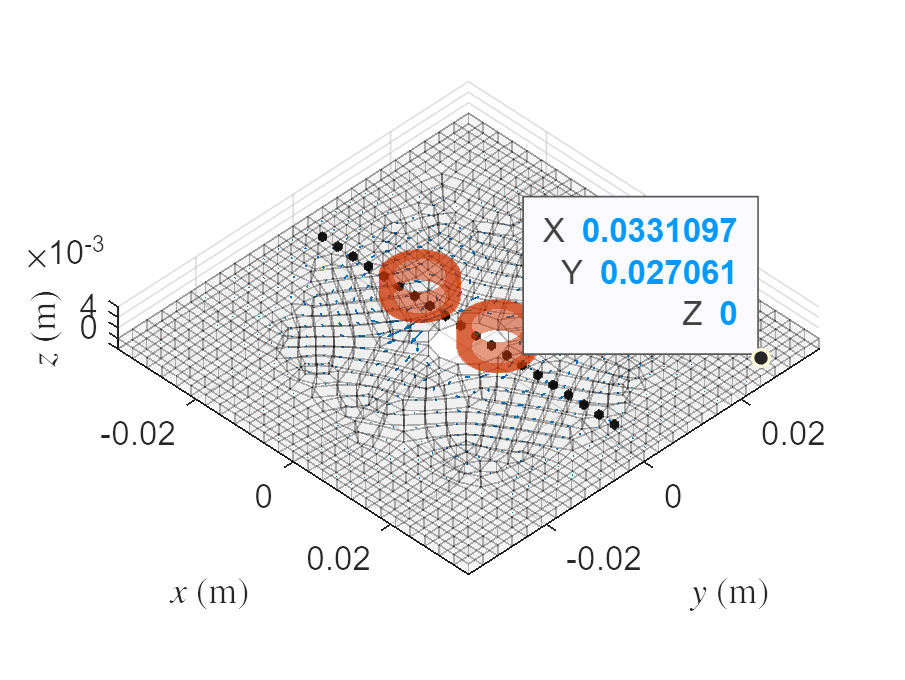

pos = Model.elms_center;
vec = real(Model.frequency_domain.J);
quiver3(pos(1,:),pos(2,:),pos(3,:), vec(1,:),vec(2,:),vec(3,:));
clear pos vec

PlotWorld3D(Model, EM, Sensor);

clf